# PRM con REDD SHEPS CURVES

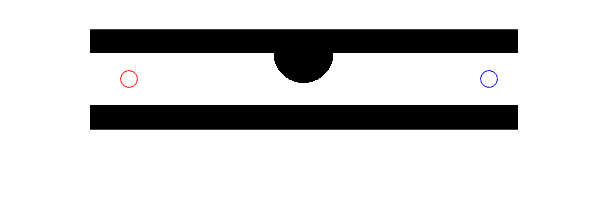

% Carica la mappa da un file .mat (assumendo che contenga una variabile 'map')
load('map_straight_with_roundabout.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

x_start = 40;
y_start = 50;
x_goal = 400;
y_goal = 50;

% Definizione di punti di partenza e arrivo
Qs = [x_start, y_start];  % Coordinata di partenza
Qg = [x_goal, y_goal];    % Coordinata di arrivo

% Plot initialization
figure;
imshow(map_straight_with_roundabout);
hold on;

% Plotting the start and goal points on the map
plot(x_start, y_start, 'ro', 'MarkerSize', 10); % Start point (red)
plot(x_goal, y_goal, 'bo', 'MarkerSize', 10); % Goal point (blue)


% Parametri per l'algoritmo PRM
numNodes = 10;         % Numero di punti campione
neighborRadius = 30;    % Raggio di ricerca per trovare vicini
minDist = 10;           % Distanza minima tra i punti campione
curveResolution = 0.1;  % Risoluzione per l'interpolazione delle curve di Redd

% Genera punti campione casuali sulla mappa
samplePoints = generateRandomPoints(numNodes, map);

% Costruisci il grafo PRM
graph = buildPRMGraph(samplePoints, neighborRadius, minDist, map);

% Trova il percorso utilizzando A* o un altro algoritmo di ricerca del percorso
pathNodes = findPath(graph, Qs, Qg);

% Interpola la traiettoria utilizzando le curve di Redd Sheeps
smoothPath = interpolateReddSheeps(pathNodes, curveResolution);

% Visualizza la mappa e il percorso
figure;
imshow(map);
hold on;
plotPath(smoothPath, 'LineWidth', 2);
plot(Qs(1), Qs(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(Qg(1), Qg(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
title('Percorso generato con PRM e curve di Redd Sheeps');
hold off;

% Funzioni ausiliarie

function points = generateRandomPoints(numPoints, map)
    % Genera punti casuali sulla mappa
    [rows, cols] = size(map);
    points = [];
    while size(points, 1) < numPoints
        x = randi(cols);
        y = randi(rows);
        if map(y, x) == 0  % Assicura che il punto non sia all'interno di un ostacolo
            points = [points; x, y];
        end
    end
end

function graph = buildPRMGraph(samplePoints, neighborRadius, minDist, map)
    % Costruisce il grafo PRM
    nPoints = size(samplePoints, 1);
    graph.Nodes = samplePoints;
    graph.Edges = cell(nPoints, 1);
    
    % Utilizza una ricerca spaziale per trovare vicini
    kdTree = KDTreeSearcher(samplePoints);
    for i = 1:nPoints
        % Trova i vicini entro il raggio specificato
        idx = rangesearch(kdTree, samplePoints(i,:), neighborRadius);
        
        % Valida i collegamenti e aggiungi archi validi al grafo
        for j = 1:length(idx)
            if idx{j} ~= i && minDist <= norm(samplePoints(i,:) - samplePoints(idx{j},:))
                if isValidEdge(samplePoints(i,:), samplePoints(idx{j},:), map)
                    graph.Edges{i} = [graph.Edges{i}; idx{j}];
                end
            end
        end
    end
end

function valid = isValidEdge(point1, point2, map)
    % Verifica se il collegamento tra point1 e point2 è valido sulla mappa
    line = [linspace(point1(1), point2(1), 50); linspace(point1(2), point2(2), 50)];
    x_line = round(line(1, :));
    y_line = round(line(2, :));
    
    % Verifica che ogni punto sulla linea non sia un ostacolo
    valid = all(map(sub2ind(size(map), y_line, x_line)) == 0);
end

function pathNodes = findPath(graph, Qs, Qg)
    % Trova il percorso utilizzando A* o un altro algoritmo di ricerca del percorso
    nNodes = size(graph.Nodes, 1);
    startNode = nearestNeighbor(graph.Nodes, Qs);
    goalNode = nearestNeighbor(graph.Nodes, Qg);
    
    % Implementazione di A* per trovare il percorso
    costs = inf(nNodes, 1);
    parents = zeros(nNodes, 1);
    costs(startNode) = 0;
    openSet = startNode;
    
    while ~isempty(openSet)
        [~, current] = min(costs(openSet));
        currentNode = openSet(current);
        
        if currentNode == goalNode
            break;
        end
        
        openSet(current) = [];
        
        for i = 1:length(graph.Edges{currentNode})
            neighbor = graph.Edges{currentNode}(i);
            tentativeCost = costs(currentNode) + norm(graph.Nodes(currentNode,:) - graph.Nodes(neighbor,:));
            
            if tentativeCost < costs(neighbor)
                parents(neighbor) = currentNode;
                costs(neighbor) = tentativeCost;
                if ~any(openSet == neighbor)
                    openSet = [openSet; neighbor];
                end
            end
        end
    end
    
    % Costruisci il percorso trovato
    path = [];
    node = goalNode;
    while node ~= 0
        path = [graph.Nodes(node, :); path];
        node = parents(node);
    end
    
    pathNodes = path;
end

function smoothPath = interpolateReddSheeps(pathNodes, resolution)
    % Interpola la traiettoria utilizzando le curve di Redd Sheeps
    nPoints = size(pathNodes, 1);
    smoothPath = pathNodes(1, :);
    
    for i = 2:nPoints
        dist = norm(pathNodes(i, :) - pathNodes(i-1, :));
        numSegments = ceil(dist / resolution);
        x_interp = linspace(pathNodes(i-1, 1), pathNodes(i, 1), numSegments);
        y_interp = linspace(pathNodes(i-1, 2), pathNodes(i, 2), numSegments);
        smoothPath = [smoothPath; [x_interp(2:end-1)', y_interp(2:end-1)']];
    end
    
    smoothPath = [smoothPath; pathNodes(end, :)];
end

function plotPath(path, varargin)
    % Funzione di supporto per visualizzare il percorso sulla mappa
    plot(path(:,1), path(:,2), varargin{:});
end